clc, clearvars;

defaultSimLocation = 'D:\Creo_Simulations';
currentDateTime = char(datetime('now', 'Format','yyyy_MM_dd__hh_mm'));

loadType = 'new';
coolerArea_mm2 = 164.0;
Tgoal = 150.0;

switch loadType
    case 'new'
        [~,creoResultsLocation] = uigetfile_extended('xlsx', defaultSimLocation);

        % Get a list of all .xlsx files in the designated location
        fileList = dir(fullfile(creoResultsLocation, '*.xlsx'));
        fileNames = {fileList.name}';

        % Names to remove
        namesToRemove = {''}; % Change these to the names you want to remove
        % Remove names matching the provided names
        filteredFileNames = setdiff(fileNames, namesToRemove);
        % Create a struct with fields as filenames' last characters after '_' without file extension
        S = struct();
        for i = 1:length(filteredFileNames)
            [~, name, ~] = fileparts(filteredFileNames{i});
            splittedFileName = split(name, '_');
            filedName = splittedFileName{end}; % Get the last character after '_'
            S.(filedName) = readtable(fullfile(creoResultsLocation, filteredFileNames{i}));
        end
        
        matFileName_ = split(creoResultsLocation, '\');
        matFileName = [matFileName_{end-1} '_' currentDateTime '.mat'];
        save(matFileName, 'S');
        sprintf('File %s was saved...', matFileName)
    case 'load'
        dirRes = dir('*.mat');
        if isempty(dirRes)
            error('No .mat files found.');
        end
        fileNames = {dirRes.name};

        [idx, ok] = listdlg( ...
            'PromptString', 'Select a MAT file:', ...
            'SelectionMode', 'single', ...
            'ListString', fileNames);

        selectedFile = fileNames{idx};
        disp(['Selected file: ', selectedFile]);
        load(selectedFile);
end

ans = 'File EXPC_COOLING_v12_2_8_2026_01_27__03_15.mat was saved...'

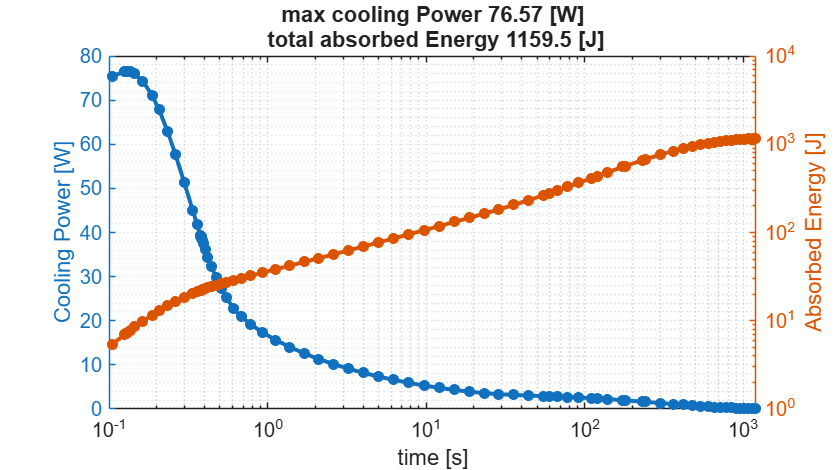

coolingPower = S.heatFlux.Heat_flux * coolerArea_mm2 * 1e-6;
totalEnergy_J = cumtrapz(S.heatFlux.Time, coolingPower);
maxCoolPower = max(coolingPower);

figure('Units','normalized', 'Position',[0 0 0.85 0.85])

yyaxis left
semilogx(S.heatFlux.Time, coolingPower,'-o' ,'LineWidth', 3.0, 'Marker','.', 'MarkerSize',25.0);
ylabel('Cooling Power [W]');
xlabel('time [s]');
title(sprintf('max cooling Power %.2f [W]\n total absorbed Energy %.1f [J]', maxCoolPower, totalEnergy_J(end)));
set(gca, 'FontSize', 15);
grid minor
yyaxis right
loglog(S.heatFlux.Time, totalEnergy_J,'-o' ,'LineWidth', 3.0, 'Marker','.', 'MarkerSize',25.0);
ylabel('Absorbed Energy [J]');
xlim([0.1 1200])

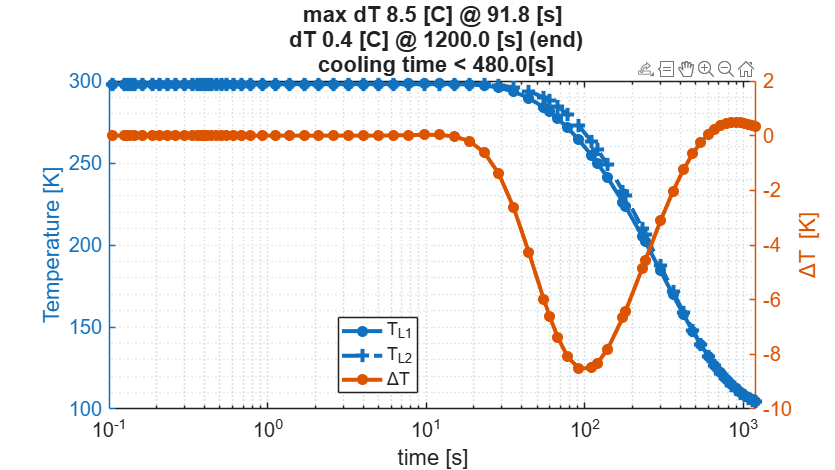

T1 = S.L1.temp_at_point_L1_S1_VERTEX + 273.15;
T2 = S.L2.temp_at_point_L2_S1_VERTEX + 273.15;

dT_L1L2 = T1 - T2;
[dT_L1L2_max, indx] = max(abs(dT_L1L2));
t_dT_L1L2_max = S.L1.Time(indx);
dT_L1L2_end = abs(dT_L1L2(end));

indx1 = find(T1 < Tgoal, 1, 'first');
indx2 = find(T2 < Tgoal, 1, 'first');

tCooling = S.L1.Time((max(indx1, indx2)));

figure('Units','normalized', 'Position',[0 0 0.85 0.85])
yyaxis left
semilogx(S.L1.Time,  S.L1.temp_at_point_L1_S1_VERTEX + 273.15,'-o' ,...
    'LineWidth', 3.0, 'Marker','.', 'MarkerSize',25.0,...
    'DisplayName','T_{L1}'); hold on;
semilogx(S.L2.Time, S.L2.temp_at_point_L2_S1_VERTEX + 273.15,'--' ,...
    'LineWidth', 3.0, 'Marker','+', 'MarkerSize',10.0,...
    'DisplayName','T_{L2}');
ylabel('Temperature [K]');
xlabel('time [s]');
legend('show', 'Location','best');
title(sprintf('max dT %.1f [C] @ %.1f [s]\n dT %.1f [C] @ %.1f [s] (end)\n cooling time < %.1f[s]',...
dT_L1L2_max, t_dT_L1L2_max, dT_L1L2_end,  S.L1.Time(end), tCooling));
set(gca, 'FontSize', 15);

yyaxis right
semilogx(S.L1.Time, dT_L1L2,...
    '-' , 'LineWidth', 3.0, 'Marker','.', 'MarkerSize',25.0, 'DisplayName','\DeltaT');
xlim([0.1 1200])
ylabel('\DeltaT [K]');
grid minor

figure('Units','normalized', 'Position',[0 0 0.85 0.85])

semilogx(S.DEG0P000.Time, S.DEG0P000.temp_H_0DEG_PNT1, 'DisplayName', '0_{DEG} 00[%]', 'LineWidth', 3.0); hold on

Unrecognized field name "DEG0P000".

semilogx(S.DEG0P025.Time, S.DEG0P025.temp_H_0DEG_PNT2,'--','DisplayName', '0_{DEG} 25[%]', 'LineWidth', 3.0);
semilogx(S.DEG0P050.Time, S.DEG0P050.temp_H_0DEG_PNT3, 'DisplayName', '0_{DEG} 50[%]', 'LineWidth', 3.0);
semilogx(S.DEG0P075.Time, S.DEG0P075.temp_H_0DEG_PNT4, 'DisplayName', '0_{DEG} 75[%]', 'LineWidth', 3.0);
semilogx(S.DEG0P100.Time, S.DEG0P100.temp_H_0DEG_PNT5, 'DisplayName', '0_{DEG} 100[%]', 'LineWidth', 3.0);
legend('show')
ylabel('Temperature [K]');
xlabel('time [s]');
legend('show');
title('Temperature Distribution - Housing Upper (Cooled) Surface');
grid minor
set(gca, 'FontSize', 15);

figure('Units','normalized', 'Position',[0 0 0.85 0.85])

semilogx(S.DEG90P000.Time, S.DEG90P000.temp_H_90DEG_PNT1, 'DisplayName', '90_{DEG} 00[%]', 'LineWidth', 3.0); hold on
semilogx(S.DEG90P025.Time, S.DEG90P025.temp_H_90DEG_PNT2, 'DisplayName', '90_{DEG} 25[%]', 'LineWidth', 3.0);
semilogx(S.DEG90P050.Time, S.DEG90P050.temp_H_90DEG_PNT3, 'DisplayName', '90_{DEG} 50[%]', 'LineWidth', 3.0);
semilogx(S.DEG90P075.Time, S.DEG90P075.temp_H_90DEG_PNT4, 'DisplayName', '90_{DEG} 75[%]', 'LineWidth', 3.0);
semilogx(S.DEG90P100.Time, S.DEG90P100.temp_H_90DEG_PNT5, 'DisplayName', '90_{DEG} 100[%]', 'LineWidth', 3.0);
legend('show')
ylabel('Temperature [K]');
xlabel('time [s]');
legend('show');
title('Temperature Distribution - Housing Side Surface');
grid minor
set(gca, 'FontSize', 15);

figure('Units','normalized', 'Position',[0 0 0.85 0.85])

semilogx(S.DEG180P000.Time, S.DEG180P000.temp_H_180DEG_PNT1, 'DisplayName', '180_{DEG} 00[%]', 'LineWidth', 3.0); hold on
semilogx(S.DEG180P025.Time, S.DEG180P025.temp_H_180DEG_PNT2, 'DisplayName', '180_{DEG} 25[%]', 'LineWidth', 3.0);
semilogx(S.DEG180P050.Time, S.DEG180P050.temp_H_180DEG_PNT3, 'DisplayName', '180_{DEG} 50[%]', 'LineWidth', 3.0);
semilogx(S.DEG180P075.Time, S.DEG180P075.temp_H_180DEG_PNT4, 'DisplayName', '180_{DEG} 75[%]', 'LineWidth', 3.0);
semilogx(S.DEG180P100.Time, S.DEG180P100.temp_H_180DEG_PNT5, 'DisplayName', '180_{DEG} 100[%]', 'LineWidth', 3.0);
legend('show', 'Location','best')
ylabel('Temperature [K]');
xlabel('time [s]');
legend('show');
title('Temperature Distribution - Housing Bottom Surface');
grid minor
set(gca, 'FontSize', 15);